# 2-QAM

## Generate Data for Transmission

rng(1) % Seed the random number generator
N=4000-100; % Length of the data
dat=sign(randn(N,1))+1i*sign(randn(N,1)); % Generate random data
txname='+pointless.dat'; % name of the tx data file

% start transmission with 100 -1s
negative = -1*ones(100,1)-1i*ones(100,1);
dat= [negative.' dat.'].'

dat =   -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i



% Upsample the data
pulse_width = 100;
x_us=upsample(dat,pulse_width);

% Convolve the signal with a pulse
pulse=ones(pulse_width,1);
x=conv(x_us,pulse,'same');

% Write TX data to a file
write_usrp_data_file(x,txname)

## Frequency Response Estimation

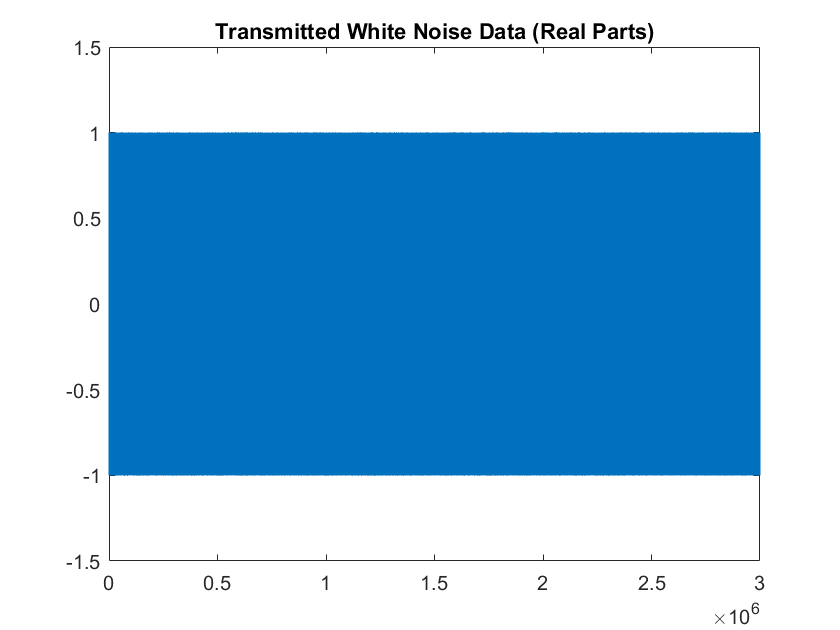

% Read in the Received White Noise
txwhitename='white_noise_input_3_million.dat';
rxwhitename='white_noise_output_1.dat';
white_noise_out=read_usrp_data_file(rxwhitename);
white_noise_in=read_usrp_data_file(txwhitename);

plot(real(white_noise_in))
title('Transmitted White Noise Data (Real Parts)')
ylim([-1.5,1.5]);

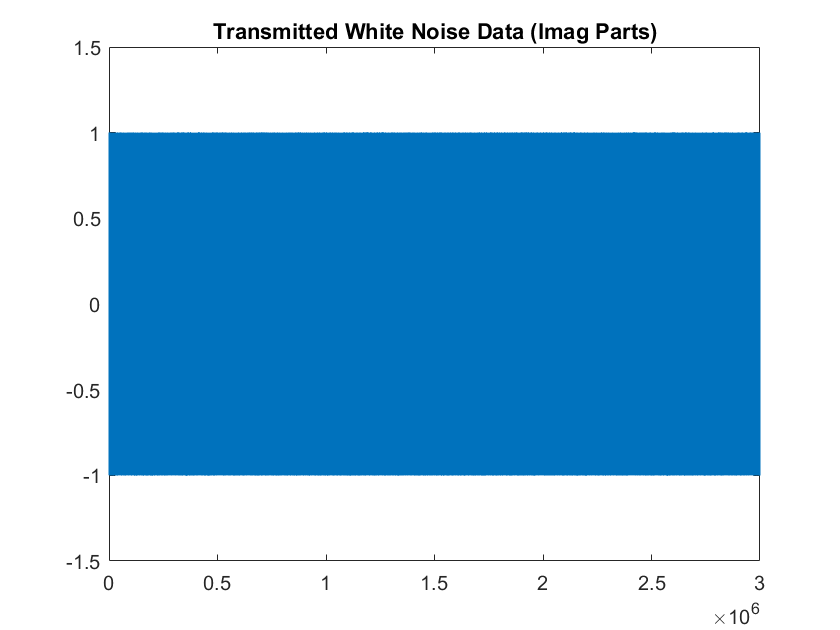


% Plot the imaginary part of the tx data
figure
plot(imag(white_noise_in))
title('Transmitted White Noise Data (Imag Parts)')
ylim([-1.5,1.5]);

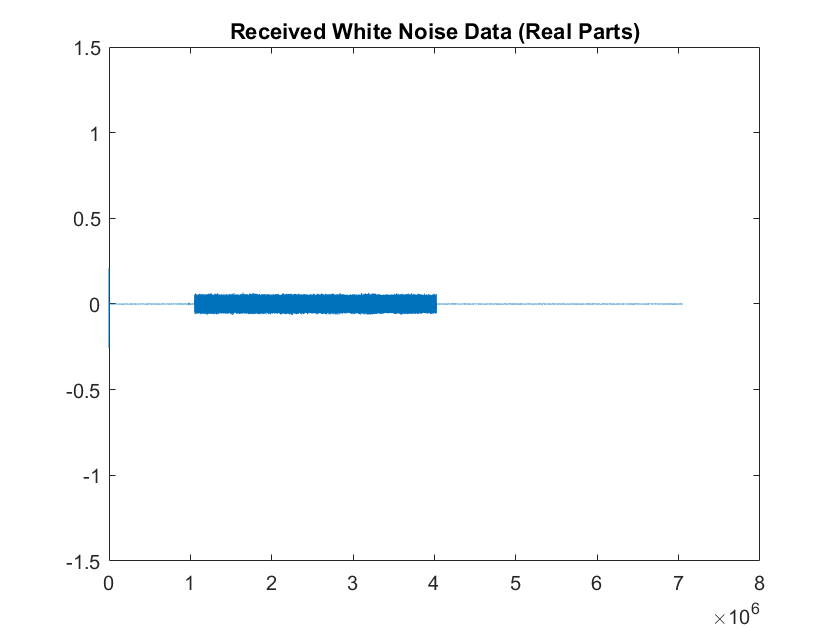


plot(real(white_noise_out))
title('Received White Noise Data (Real Parts)')
ylim([-1.5,1.5]);

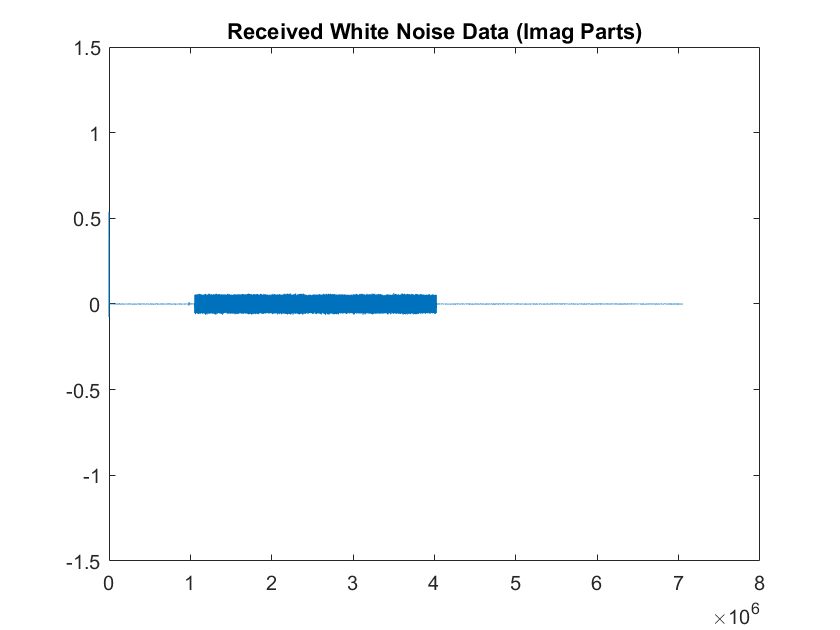


% Plot the imaginary part of the tx data
figure
plot(imag(white_noise_out))
title('Received White Noise Data (Imag Parts)')
ylim([-1.5,1.5]);

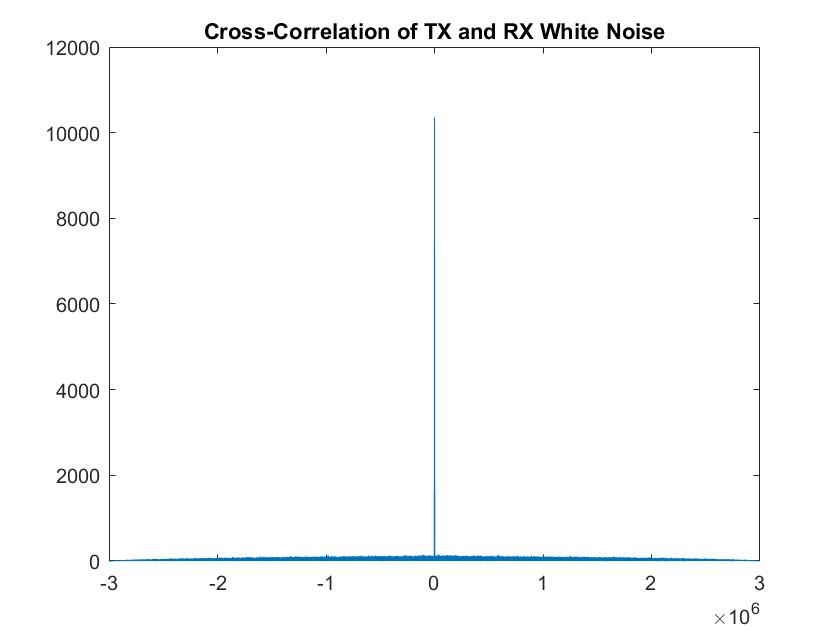



%Find auto-correlation of received white noise
[r_white, lags_white]=xcorr(real(white_noise_in), real(white_noise_out));
startPosw = abs(lags_white(find(abs(r_white) == max(abs(r_white)))));
white_noise_out_clipped = white_noise_out(startPosw:startPosw+length(white_noise_in)-1);
[r_white_c, lags_white_c]=xcorr(real(white_noise_in), real(white_noise_out_clipped));

% Plot cross-correlation
plot(lags_white_c,abs(r_white_c))
title('Cross-Correlation of TX and RX White Noise')

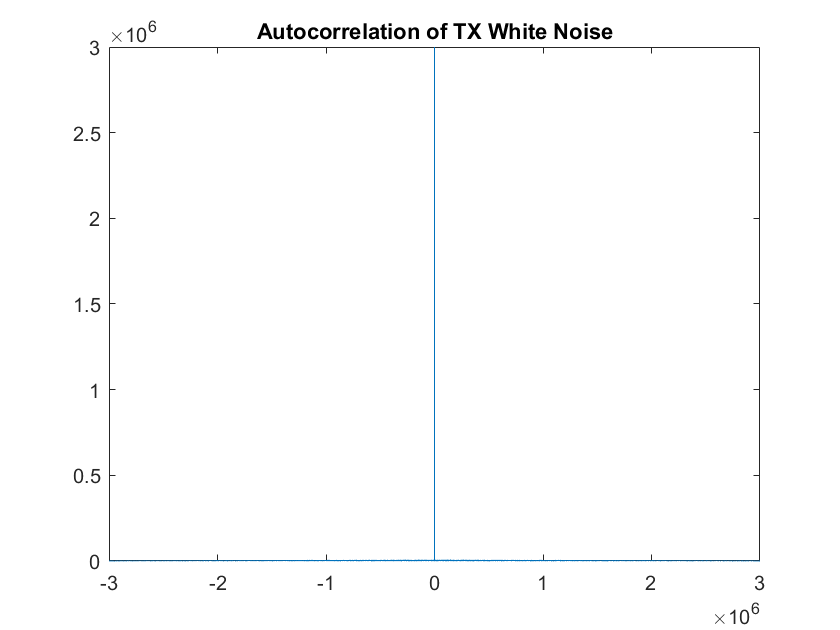


% Plot TX autocorrelation
% [rw_in, lagsw_in]=xcorr(real(white_noise_in), real(white_noise_in));
% plot(lagsw_in, abs(rw_in));
% title('Autocorrelation of TX White Noise');

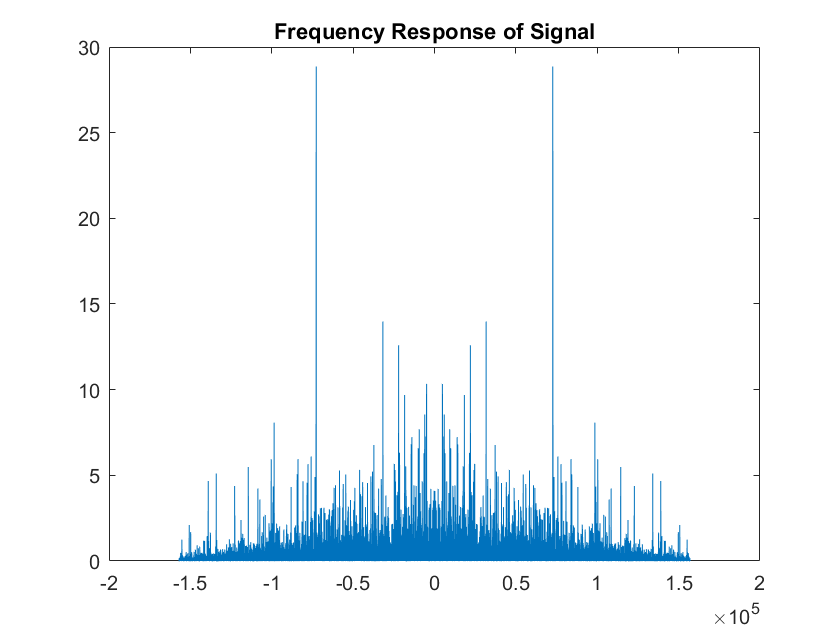


% Plot autocorrelation in frequency domain
% fft_in = abs(fftshift(fft(rw_in)));
fft_cross = abs(fftshift(fft(r_white_c)));
h_f = fft_cross; %./ fft_in;
Fs = 500000;
x_data = 2*pi*linspace(-Fs/2, Fs/2*(length(r_white_c)-1)/length(r_white_c), length(r_white_c));
plot(x_data, h_f)
title('Frequency Response of Signal')

%h_f  = y_data;

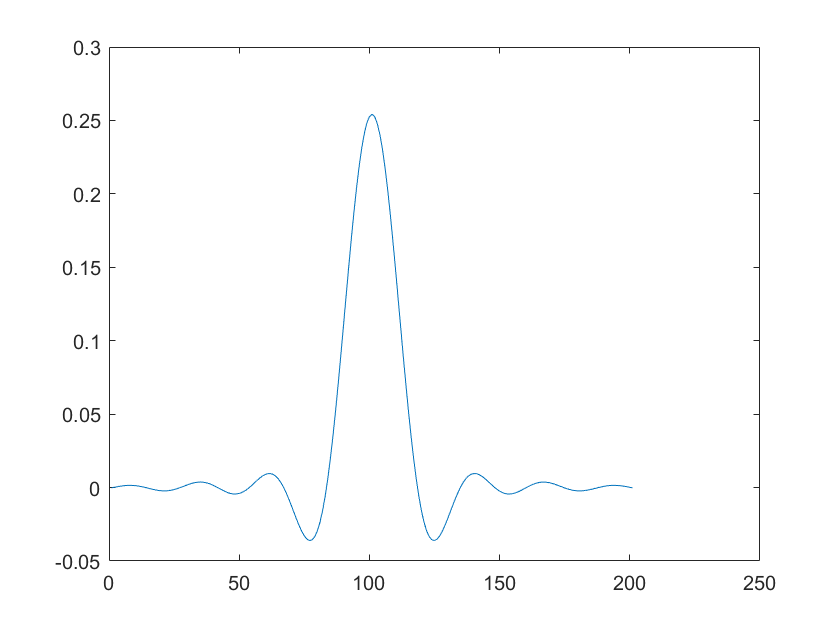

% Design P(f)
T = 20; % Symbol Period
rrc = rcosdesign(0.5,10,T, 'sqrt');   % creates a root-raised cosine 
                                      % filter which when combined with a 
                                      % matched filter results in 
                                      % zero crossings every 
                                      % T. Rolloff factor of 0.5
                                      % 20 x 3 samples are returned 
                                      % (in theory the raised cosine
                                      % impulse response is infinite, but
                                      % is truncated to T x 20 samples)
%p_f = rrc ./ h_f;
plot(rrc)

rrc_freq = fftshift(fft(rrc));

p_f = rrc_freq.' ./ h_f;

Matrix dimensions must agree.

plot(p_f)

## Read in Transmitted Data

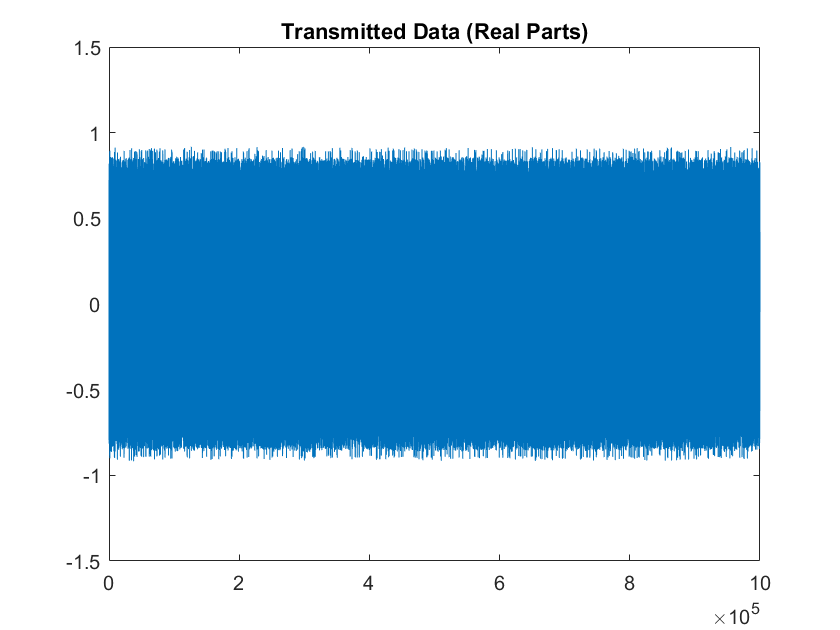

% Read in the Transmitted Data
txname='tx_rrc1.dat';
dat=read_usrp_data_file(txname);

% Plot the real part of the tx data
figure
plot(real(dat))
title('Transmitted Data (Real Parts)')
ylim([-1.5,1.5]);

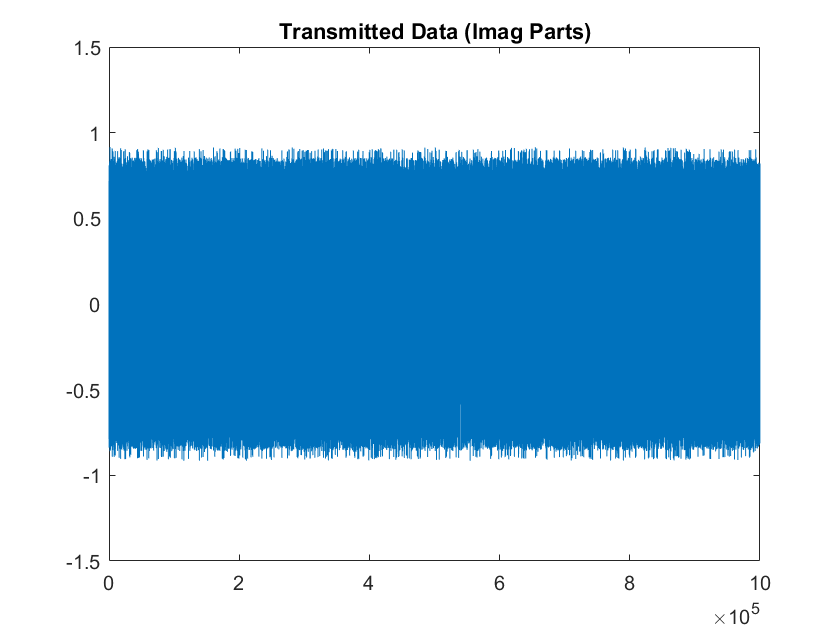


% Plot the imaginary part of the tx data
figure
plot(imag(dat))
title('Transmitted Data (Imag Parts)')
ylim([-1.5,1.5]);


% Plot the real part vs the imaginary part of the tx
figure
plot(real(dat),imag(dat), 'o')
ylim([-1.5,1.5])
xlim([-1.5,1.5])
title('Transmitted Data - Re vs Im')
xlabel('Real Component')
ylabel('Imaginary Component')

## Read in the Received Data

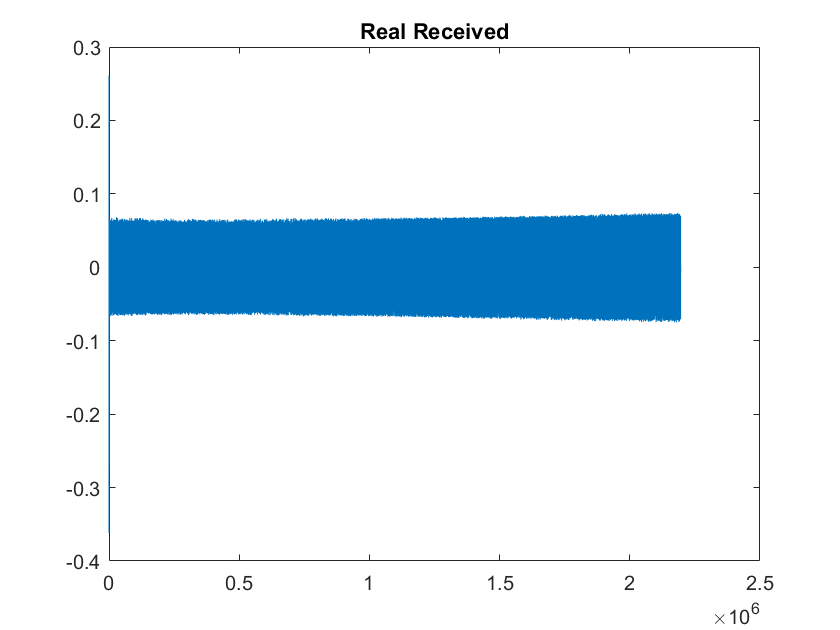

% Read in the received data
rxname='rrc_direct_1million_sampling.dat';
read=read_usrp_data_file(rxname);

% Plot the real part of rx
figure
plot(real(read))
%ylim([-1.5,1.5]);
title('Real Received')

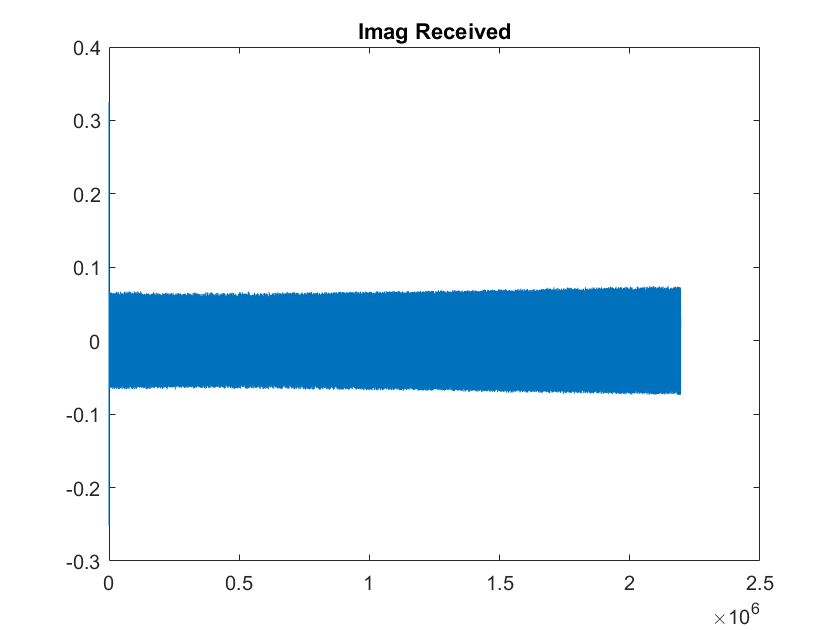


% Plot the imaginary part of rx
figure
plot(imag(read))
title('Imag Received')

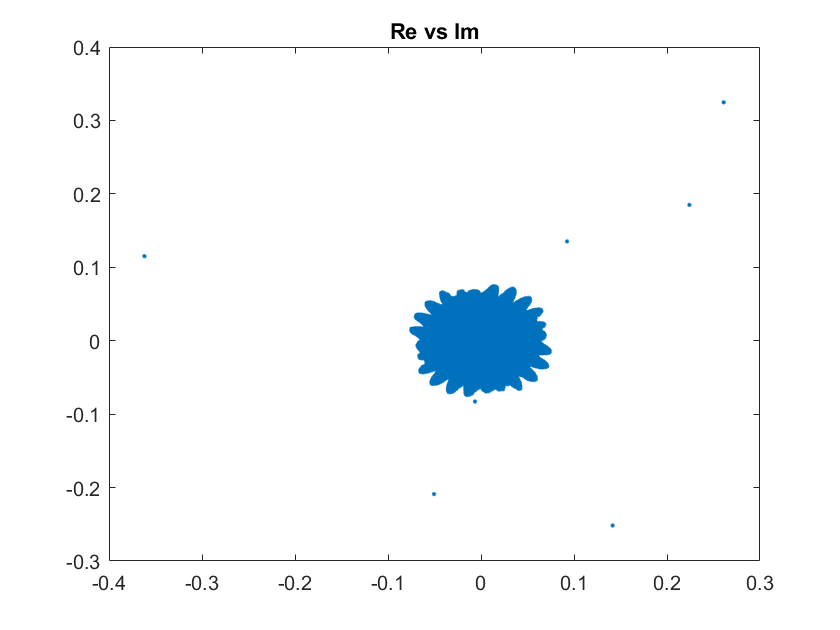


% Plot real vs imaginary components of the rx signal
figure
plot(real(read),imag(read),'.')
title('Re vs Im')

## Cross-correlation of RX and TX

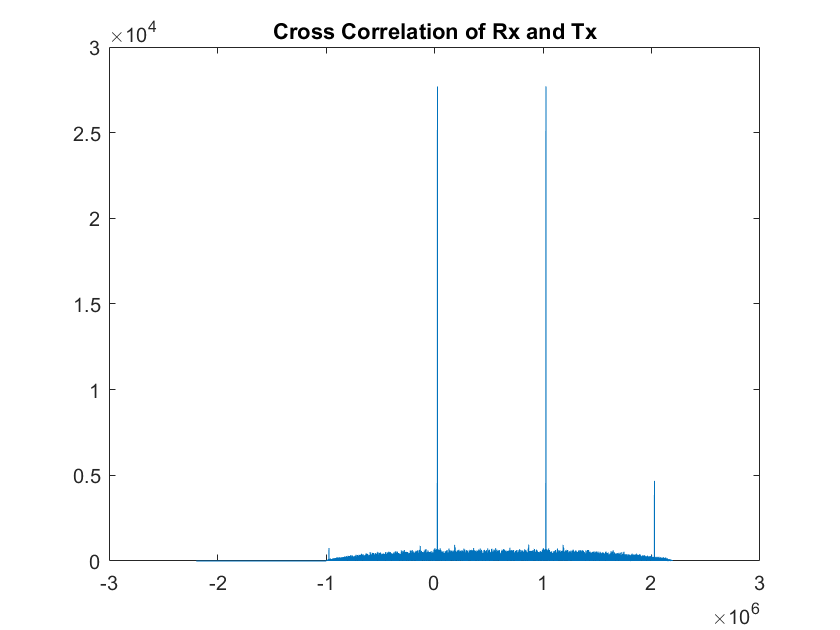

%Find cross-correlation of received and transmitted signals
[r, lags]=xcorr(read,dat);

% Plot Cross-correlation
plot(lags,abs(r))
title('Cross Correlation of Rx and Tx')

% xlim([-10^5 10^5])
% ylim([-.2 .2])

% Find the lag where the cross-correlation of rx/tx is greatest
% This indicates where the signal begins
startPos = abs(lags(find(abs(r) == max(abs(r)))))

startPos = 1027201

## Adjust for phase shift

% Isolate the portion of the received signal corresponding to the data we
% sent
read_shifted=read(startPos:end);
signal_rx = read_shifted(1:length(dat));

% Create RRC Filter
T = 100; % Symbol Period
pulse_width=100;
span = 20;
rolloff = 0.5

rolloff = 0.5000

rrc = rcosdesign(rolloff,span,T, 'sqrt') 

rrc =     0.1596    0.1596    0.1592    0.1585    0.1575    0.1561    0.1543    0.1522    0.1497    0.1469    0.1438    0.1403    0.1365    0.1323    0.1279    0.1231    0.1181    0.1127    0.1071    0.1012    0.0950    0.0887    0.0820    0.0752    0.0682    0.0609    0.0535    0.0460    0.0383    0.0305    0.0226    0.0145    0.0065   -0.0017   -0.0099   -0.0181   -0.0263   -0.0345   -0.0427   -0.0508   -0.0588   -0.0668   -0.0746   -0.0824   -0.0899   -0.0974   -0.1046   -0.1117   -0.1186   -0.1252


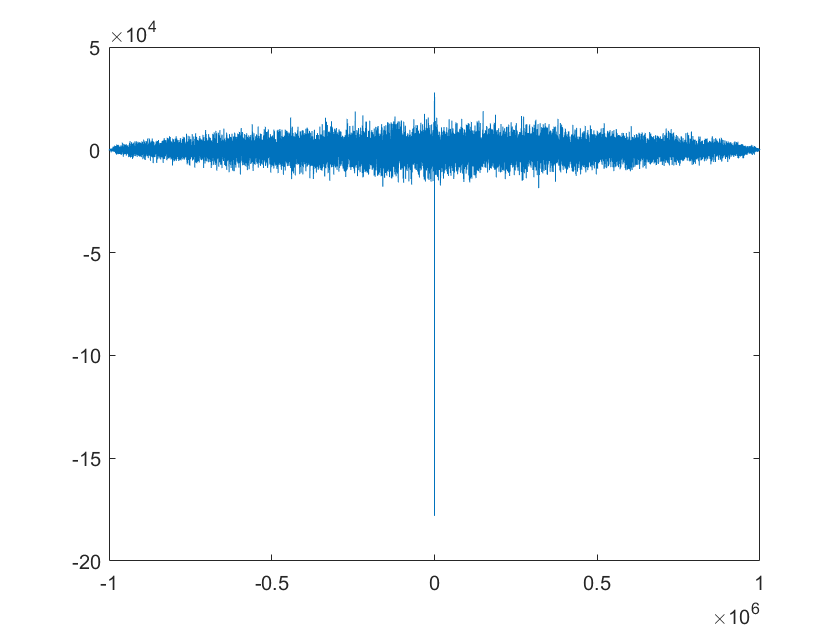


% Cross-correlate real part of received signal and transmitted signal
% Tells us if our start position for the signal is correct
rx_mag_1 = sign(real(signal_rx)) + sign(imag(signal_rx));
[r, lags]=xcorr(real(rx_mag_1),real(dat));
plot(lags,r)


% If our signal always begins with -1s, we can fix the sign of our received
% data by multiplying by the negative of the sign of the first bit of the
% received data
signal_rx_sign = conv(signal_rx,rrc,'same'); % sign(signal_rx(1))*signal_rx;

% Solve for phi
% y[k]=x[k]e^j*(f_delta*k+phi)+n[k]
% x[k]=e^j(pi/4 + m*pi/2)
% y[k]^4 = e^(j*pi) * e^(4*f_delta*k+4*theta)
y_norm=signal_rx_sign./rms(abs(signal_rx_sign));
y_norm_4=y_norm.^4;

% Find the maximum values of the real and imaginary components of the fft
% of y[k]^4
fft_y = fftshift(fft(y_norm_4));
Fs = 1000000; % sampling frequency
fft_x = 2*pi*linspace(-Fs/2, Fs/2*(length(y_norm_4)-1)/length(y_norm_4), length(y_norm_4));
real_max = max(real(fft_y));
real_min = min(real(fft_y));
if abs(real_min) > abs(real_max)
    real_max = real_min;
end
im_max = max(imag(fft_y));
im_min = min(imag(fft_y));
if abs(im_min) > abs(im_max)
    im_max = im_min;
end
%plot(fftshift(real(fft_y)))

% 4*phi + pi = atan(im_max / real_max)
phi = (atan(im_max/real_max) - pi)/4-pi/2

phi = -1.9850


% Find complex exponential to adjust for phase offset
f_delta = fft_x(find(real(fft_y)==real_max))/4 % adjusts for clocks being unsynchronized

f_delta = 0.3927

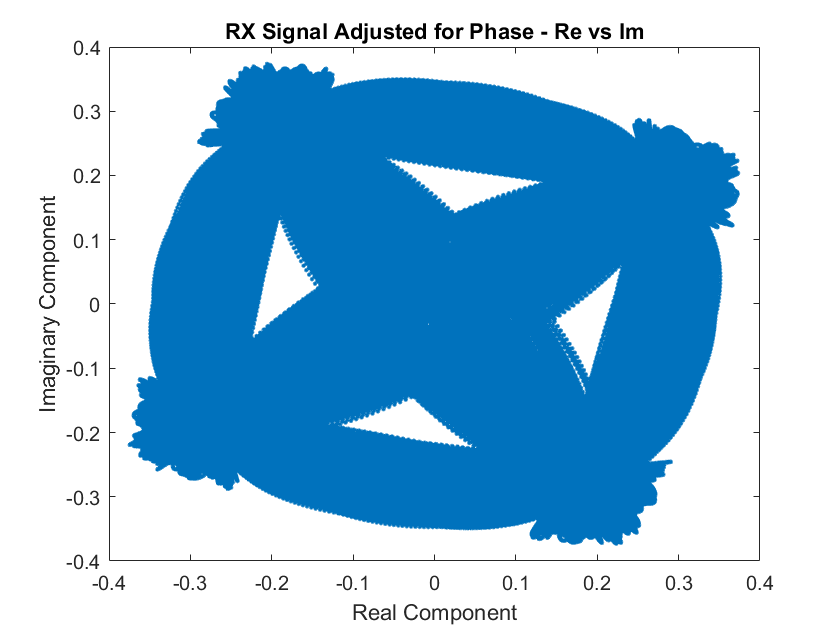

k=1:length(signal_rx_sign);
offset=exp(-j*(f_delta*(k-1)*1/Fs+phi+pi/4));

% Multiply rx signal by the complex exponential to adjust for phase offset
read_offset=times(signal_rx_sign,offset.');

% Plot real vs imaginary of adjusted rx signal
figure
plot(real(read_offset),imag(read_offset),'.')
title('RX Signal Adjusted for Phase - Re vs Im')
xlabel('Real Component')
ylabel('Imaginary Component')

## Error Calculation

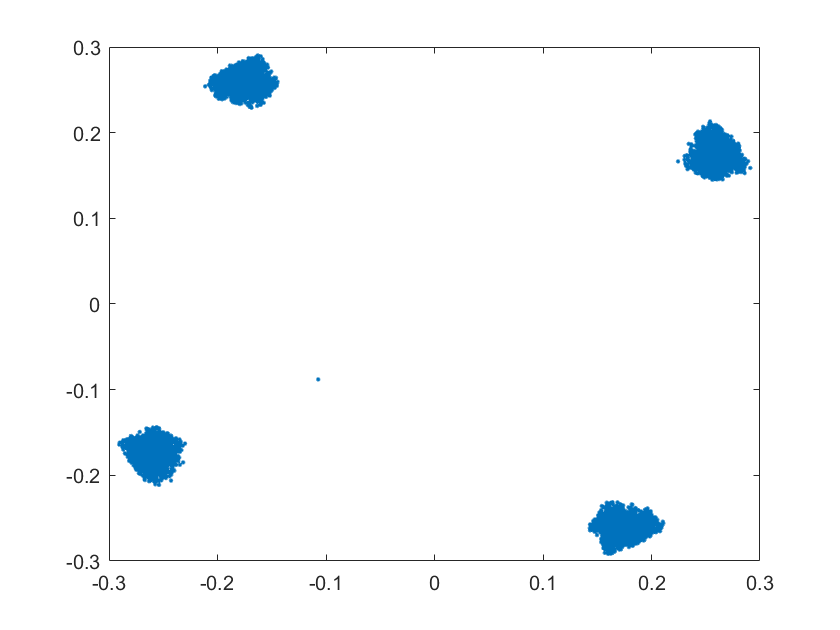

% Downsample TX signal to get original signal
data_ds = downsample(dat,pulse_width);

% Downsample RX signal
rx_ds = downsample(read_offset,pulse_width);
plot(real(rx_ds), imag(rx_ds),'.')


% Find number of errors in real and imaginary components, downsampling the
% rx signal
error_real=sign(real(rx_ds))-sign(real(data_ds));
error_imag=sign(imag(rx_ds))-sign(imag(data_ds));
err_real = length(find(error_real~=0));
err_imag = length(find(error_imag~=0));

% Sum errors and calculate error rate
err_total = err_real + err_imag;
err_rate=err_total/(length(rx_ds)*2);
err_rate

err_rate = 0

## Overlay TX and RX Signals

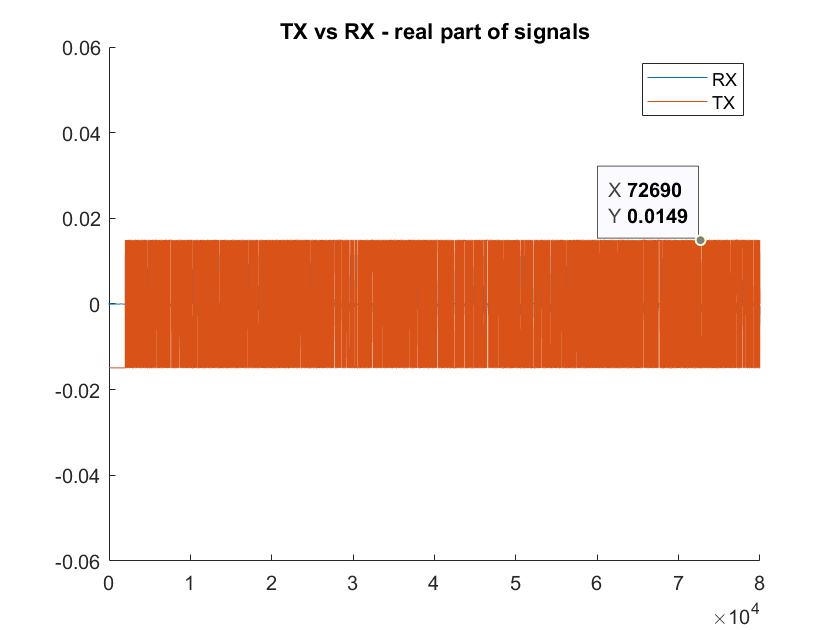

figure
hold on;
plot(real(read_offset))
plot(real(dat)*max(real(read_offset)))
legend("RX", "TX");
ylim([-.06,.06])
title("TX vs RX - real part of signals")
hold off;

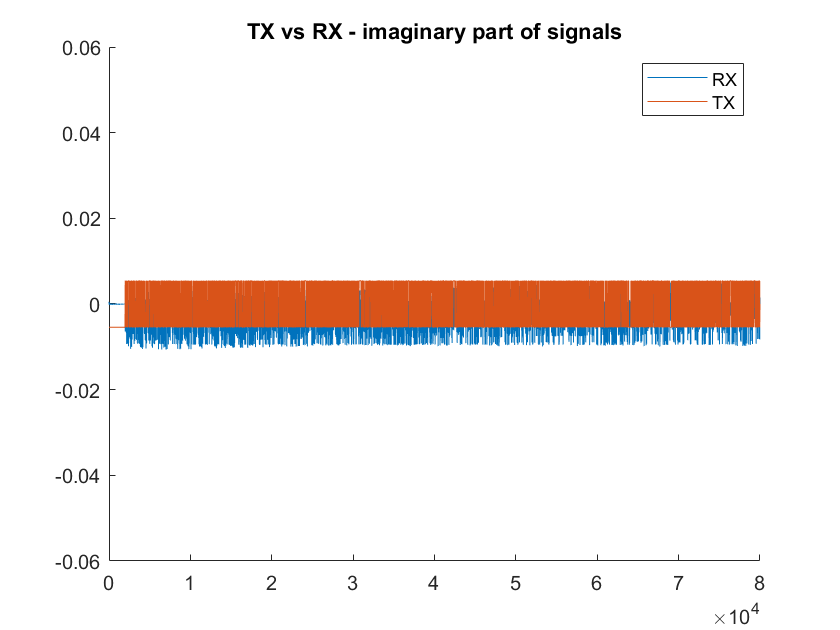


figure
hold on;
plot(imag(read_offset))
plot(imag(dat)*max(imag(read_offset)))
legend("RX", "TX");
ylim([-.06,.06])
title("TX vs RX - imaginary part of signals")
hold off;